clear;
close all;
clc;

linewidth  = 2;
fontname   = 'Times New Roman';
fontsize   = 20;
markersize = 10;

colors = [0.0000 0.0000 0.0000;
          0.0000 0.4470 0.7410;
          0.8500 0.3250 0.0980;
          0.9290 0.6940 0.1250;
          0.4940 0.1840 0.5560;
          0.4660 0.6740 0.1880;
          0.3010 0.7450 0.9330;
          0.6350 0.0780 0.1840];

## **NETWORK PARAMETERS**

N_BLK = 1000;

M = 100;
K = 4;

B = 8;
M_QAM = 2^B;

SNR = -10:1:20;
N_SNR = length(SNR);

H = (randn(M, K) + 1i * randn(M, K)) / sqrt(2);

## MEMORY ALLOCATION

s = zeros(N_BLK, K);

BER_ZF = zeros(1, N_SNR);
BER_MF = zeros(1, N_SNR);

bit_array = randi([0,1], B*N_BLK, K);

for users_idx = 1:K
    s(:, users_idx) = qammod(bit_array(:,users_idx), M_QAM, 'InputType', 'bit');
end
     
precoder_ZF = conj(H) / (H.' * conj(H));
precoder_MF = conj(H) ./ (vecnorm(H).^2);

x_ZF = precoder_ZF * s.';
x_MF = precoder_MF * s.';

x_ZF_normalized = zeros(size(x_ZF)); 
x_MF_normalized = zeros(size(x_MF));

for i = 1:size(x_ZF, 1)
    Px_ZF = abs(x_ZF(i, :)).^2;
    Px_MF = abs(x_MF(i, :)).^2;
    
    x_ZF_normalized(i, :) = x_ZF(i, :) / sqrt(Px_ZF);
    x_MF_normalized(i, :) = x_MF(i, :) / sqrt(Px_MF);
end

for snr_idx = 1:N_SNR
    snr = 10^(SNR(snr_idx)/10);
    noise_variance = 1/snr;
    v = sqrt(noise_variance/2) * (randn(size(H,2), N_BLK) + 1i*randn(size(H,2), N_BLK));

    y_ZF = H.' * x_ZF_normalized + v; 
    y_MF = H.' * x_MF_normalized + v;

    % Demodulação e cálculo da BER para ZF
    bit_received_ZF = zeros(B*N_BLK, K);
    for users_idx = 1:K
        s_received_ZF = y_ZF(users_idx, :).';
        bit_received_ZF(:, users_idx) = qamdemod(s_received_ZF, M_QAM, 'OutputType', 'bit');
    end
    bit_errors_ZF = sum(bit_array ~= bit_received_ZF, 'all');
    BER_ZF(snr_idx) = bit_errors_ZF / numel(bit_array);

    % Demodulação e cálculo da BER para MF
    bit_received_MF = zeros(B*N_BLK, K); % Reset for MF
    for users_idx = 1:K
        s_received_MF = y_MF(users_idx, :).';
        bit_received_MF(:, users_idx) = qamdemod(s_received_MF, M_QAM, 'OutputType', 'bit');
    end
    bit_errors_MF = sum(bit_array ~= bit_received_MF, 'all');
    BER_MF(snr_idx) = bit_errors_MF / numel(bit_array);
end

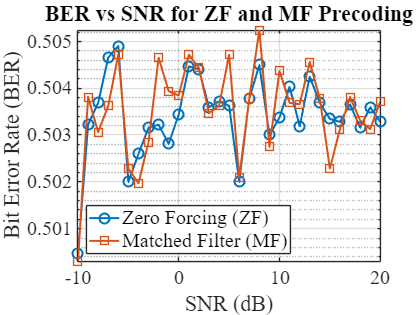

% BER vs SNR
figure;
semilogy(SNR, BER_ZF, 'o-', 'LineWidth', linewidth, 'MarkerSize', markersize, 'Color', colors(2,:)); hold on;
semilogy(SNR, BER_MF, 's-', 'LineWidth', linewidth, 'MarkerSize', markersize, 'Color', colors(3,:));
grid on;
xlabel('SNR (dB)', 'FontName', fontname, 'FontSize', fontsize);
ylabel('Bit Error Rate (BER)', 'FontName', fontname, 'FontSize', fontsize);
legend('Zero Forcing (ZF)', 'Matched Filter (MF)', 'Location', 'southwest', 'FontSize', fontsize);
title('BER vs SNR for ZF and MF Precoding', 'FontName', fontname, 'FontSize', fontsize);
set(gca, 'FontName', fontname, 'FontSize', fontsize);
hold off;

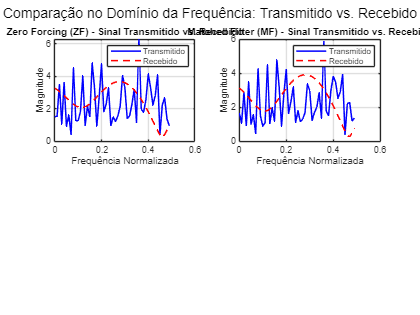

% Parâmetros de visualização
figure;

% Número de amostras
N = size(x_ZF, 1);

% Calculando a FFT dos sinais transmitidos e recebidos (Zero Forcing)
X_ZF = fft(x_ZF, N, 1);
Y_ZF = fft(y_ZF, N, 1);

% Calculando a FFT dos sinais transmitidos e recebidos (Matched Filter)
X_MF = fft(x_MF, N, 1);
Y_MF = fft(y_MF, N, 1);

% Frequências (usando a escala de frequências normalizada)
f = (0:N-1) * (1/N); % Frequência normalizada de 0 a 1

% Ajustando o eixo de frequências para mostrar apenas a metade positiva
f_shifted = f(1:floor(N/2)); 

% Plot do sinal transmitido e recebido no domínio da frequência (Zero Forcing)
subplot(2,2,1); % Dividir a figura em uma grid 2x2, plot 1
plot(f_shifted, abs(X_ZF(1:floor(N/2), 1)), 'b-', 'LineWidth', 1.5); % Sinal transmitido em azul
hold on;
plot(f_shifted, abs(Y_ZF(1:floor(N/2), 1)), 'r--', 'LineWidth', 1.5); % Sinal recebido em vermelho (linha tracejada)
title('Zero Forcing (ZF) - Sinal Transmitido vs. Recebido');
xlabel('Frequência Normalizada');
ylabel('Magnitude');
legend('Transmitido', 'Recebido');
grid on;

% Plot do sinal transmitido e recebido no domínio da frequência (Matched Filter)
subplot(2,2,2); % Plot 2
plot(f_shifted, abs(X_MF(1:floor(N/2), 1)), 'b-', 'LineWidth', 1.5); % Sinal transmitido em azul
hold on;
plot(f_shifted, abs(Y_MF(1:floor(N/2), 1)), 'r--', 'LineWidth', 1.5); % Sinal recebido em vermelho (linha tracejada)
title('Matched Filter (MF) - Sinal Transmitido vs. Recebido');
xlabel('Frequência Normalizada');
ylabel('Magnitude');
legend('Transmitido', 'Recebido');
grid on;

% Ajustar os gráficos
sgtitle('Comparação no Domínio da Frequência: Transmitido vs. Recebido', 'FontSize', 14);